# MMD_Generation

Function inputs:

- carParams: struct of car params

- rangeSA:     2x1 array of the range of SA sweap

- rangeSteer: 2x1 array of the range of steering angle sweap

- velocity:       The velocity the sim is runing under

- plots:            A boolean of if the function makes plots

- targetCAx:   Target CAx, leave it empty to run without a target CAx

Example carParams

clear;

% FE12 constants
% Chasis/suspension constants
carParams.m = 270;                        % Total Mass [kg]
carParams.PFront = 53.4/100;              % Percent Mass Front [0-1]
carParams.WB = 1.582;                     % Wheelbase [m]
carParams.TWf = 1.240;                    % Trackwidth [m]
carParams.TWr = 1.240;
carParams.toe_f = -0.5 * (pi/180);        % Toe Angles [radians] (positive is inwards)
carParams.toe_r = 0.5 * (pi/180);
carParams.hCG = 0.314;                    % CG height [m]
carParams.TireInclinationFront = -1.3; % deg 
carParams.TireInclinationRear = -1;    % deg   

% Aero constants
carParams.Cl = 3.215;
carParams.Cd = 1.468; 
carParams.CoP = 45/100;                   % front downforce distribution (%)
carParams.rho = 1.165;                    % kg/m^3
carParams.crossA = 0.9237;                % m^2

% braking system
carParams.B_FBB = 55/45;                    % Front brake bias

% Tire
tire = load('Hoosier_R20_16(18)x75(60)-10x8(7).mat');
tire.Idx = 1;                     % Moment of Inertia in x for wheel
tire.TirePressure = 70;           % kPa
tire.Model = struct( 'Pure', 'Pacejka', 'Combined', 'MNC' );
carParams.tire = tire

carParams = struct with fields:
                       m: 270
                  PFront: 0.5340
                      WB: 1.5820
                     TWf: 1.2400
                     TWr: 1.2400
                   toe_f: -0.0087
                   toe_r: 0.0087
                     hCG: 0.3140
    TireInclinationFront: -1.3000
     TireInclinationRear: -1
                      Cl: 3.2150
                      Cd: 1.4680
                     CoP: 0.4500
                     rho: 1.1650
                  crossA: 0.9237
                   B_FBB: 1.2222
                    tire: [1×1 struct]


Function outputs:

- steadyStateCAy

- absoluteCAy

- rawData

steadyState/absolute CAy contains

- CAy:       Maximum normalized accelaration

- SA:         Slip angle at maximum CAy

- dSteer:   Steering angle at maximum CAy

- Mz:         Yaw moment at maximum CAy

Example usage:

with no target CAx

%%
rangeSA = [-5,5];
rangeSteer = [-30,30];
velocity = 26.822;

% [steadyStateCAy, absoluteCAy, rawData] = MMD_Generation(carParams, rangeSA, rangeSteer, velocity, true)

with a target CAx

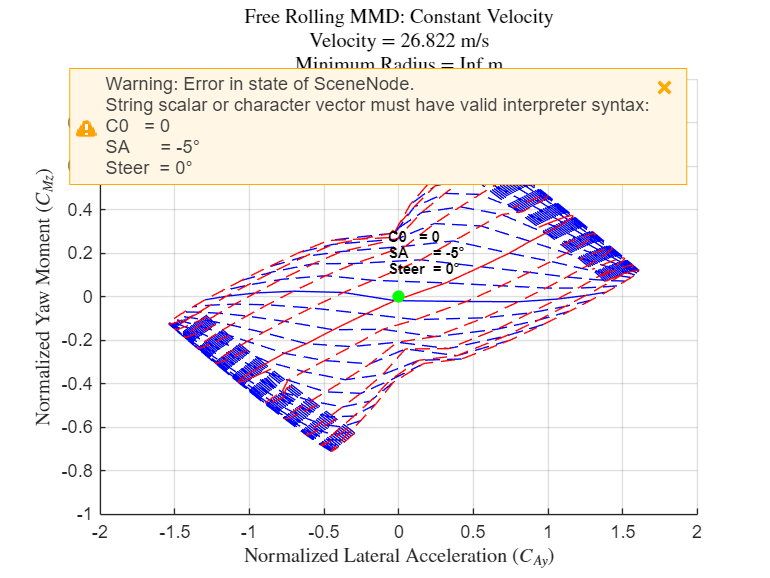

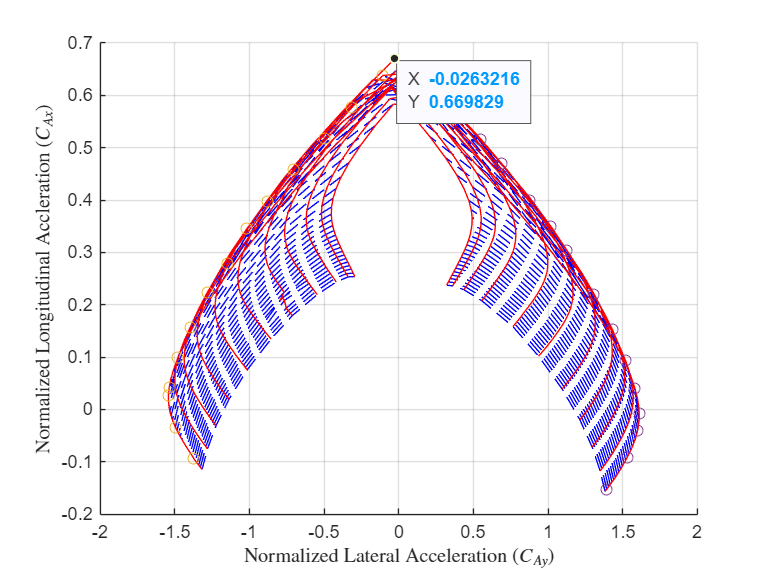

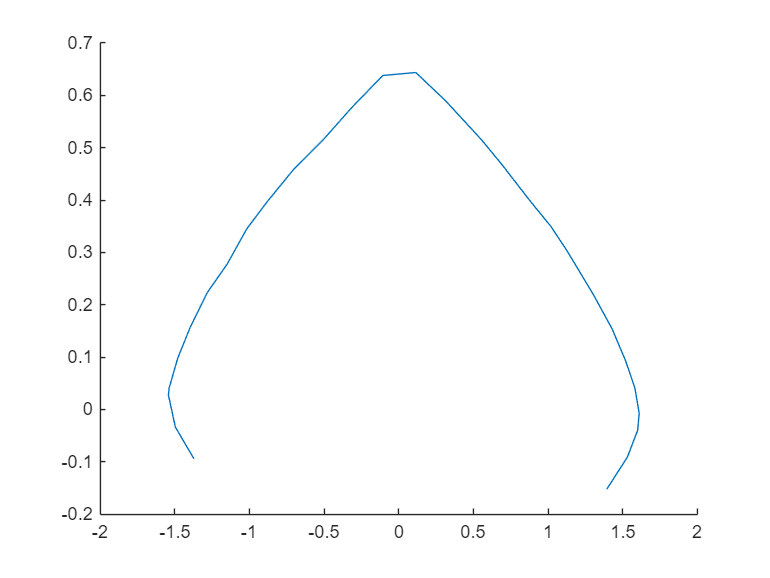

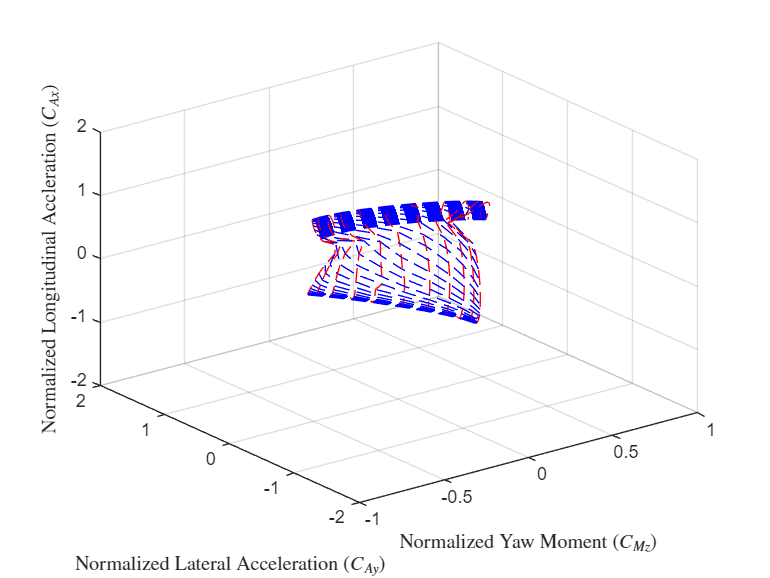

steadyStateCAy = struct with fields:
       CAy: 0
        SA: -5
    dSteer: 0
        Mz: 0


absoluteCAy = struct with fields:
       CAy: 1.6102
        SA: -0.0873
    dSteer: 0.1222
        Mz: 0.1187


rawData = struct with fields:
     saveAyBody: [61×11 double]
     saveAxBody: [61×11 double]
     saveMzBody: [61×11 double]
      saveAxVel: [61×11 double]
      saveAyVel: [61×11 double]
     saveCAyVel: [61×11 double]
     saveCAxVel: [61×11 double]
    saveCAxBody: [61×11 double]


tic;
[steadyStateCAy, absoluteCAy, rawData] = MMD_Generation(carParams, rangeSA, rangeSteer, velocity, true, 10)

toc;

Elapsed time is 59.684161 seconds.
